addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

% Configuration file was changed on xlmcon and then files were processed
% using Leah's processing pipeline 
gpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

% Uncorrected casts



% Casts with corrected SOC, E term and hysteresis 
cast07 = readSBScnv( 'uar69-01_007_KFabcdef.cnv' );
cast08 = readSBScnv( 'uar69-01_008_KFabcdef.cnv' );
cast09 = readSBScnv( 'uar69-01_009_KFabcdef.cnv' );
cast10 = readSBScnv( 'uar69-01_010_KFabcdef.cnv' );
cast11 = readSBScnv( 'uar69-01_011_KFabcdef.cnv' );
cast12 = readSBScnv( 'uar69-01_012_KFabcdef.cnv' );
cast13 = readSBScnv( 'uar69-01_013_KFabcdef.cnv' );
cast14 = readSBScnv( 'uar69-01_014_KFabcdef.cnv' );
cast16 = readSBScnv( 'uar69-01_016_KFabcdef.cnv' );
cast17 = readSBScnv( 'uar69-01_017_KFabcdef.cnv' );
cast18 = readSBScnv( 'uar69-01_018_KFabcdef.cnv' );
cast19 = readSBScnv( 'uar69-01_019_KFabcdef.cnv' );
cast20 = readSBScnv( 'uar69-01_020_KFabcdef.cnv' );
cast21 = readSBScnv( 'uar69-01_021_KFabcdef.cnv' );
cast22 = readSBScnv( 'uar69-01_022_KFabcdef.cnv' );
cast23 = readSBScnv( 'uar69-01_023_KFabcdef.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
btl = readtable('Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);
btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:);
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);
btlsum20 = btl(btl.Cast == 20,:);
btlsum21 = btl(btl.Cast == 21,:);


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')

btl07 = readtable('ar69-01_007_hyst.csv','TextType','string');

btl08 = readtable('ar69-01_008_hyst.csv','TextType','string');

btl09 = readtable('ar69-01_009_hyst.csv','TextType','string');

btl10 = readtable('ar69-01_010_hyst.csv','TextType','string');

btl11 = readtable('ar69-01_011_hyst.csv','TextType','string');

btl12 = readtable('ar69-01_012_hyst.csv','TextType','string');

btl13 = readtable('ar69-01_013_hyst.csv','TextType','string');

btl14 = readtable('ar69-01_014_hyst.csv','TextType','string');

btl16 = readtable('ar69-01_016_hyst.csv','TextType','string');

btl17 = readtable('ar69-01_017_hyst.csv','TextType','string');

btl18 = readtable('ar69-01_018_hyst.csv','TextType','string');

btl19 = readtable('ar69-01_019_hyst.csv','TextType','string');

btl20 = readtable('ar69-01_020_hyst.csv','TextType','string');

btl21 = readtable('ar69-01_021_hyst.csv','TextType','string');


% Join tables 
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13,btlsum13,'Keys',"Bottle");
btlsum14 = join(btl14,btlsum14,'Keys',"Bottle");
btlsum16 = join(btl16,btlsum16,'Keys',"Bottle");
btlsum17 = join(btl17,btlsum17,'Keys',"Bottle");
btlsum18 = join(btl18,btlsum18,'Keys',"Bottle");
btlsum19 = join(btl19,btlsum19,'Keys',"Bottle");
btlsum20 = join(btl20,btlsum20,'Keys',"Bottle");
btlsum21 = join(btl21,btlsum21,'Keys',"Bottle");

clear btl0* btl1* btl2*
btlsum_yr9 = [btlsum07; btlsum08; btlsum09; btlsum10; btlsum11; btlsum12; btlsum13;...
    btlsum14; btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21];

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
save Year9_Processed_KF cast* btl*

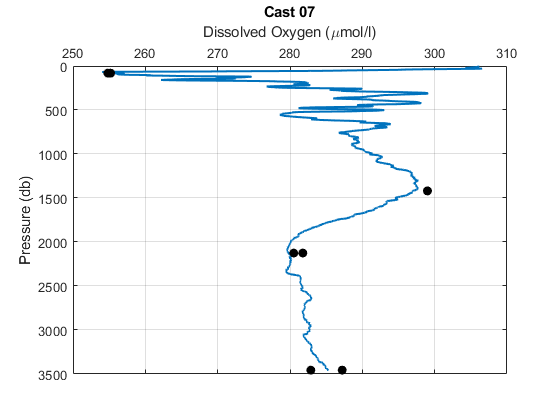

figure
plot(cast07.sbeox0mL_L*44.661,cast07.pm,'Linewidth',1.5)
hold on
plot(btlsum07.Winkler_mLL*44.661,btlsum07.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 07')

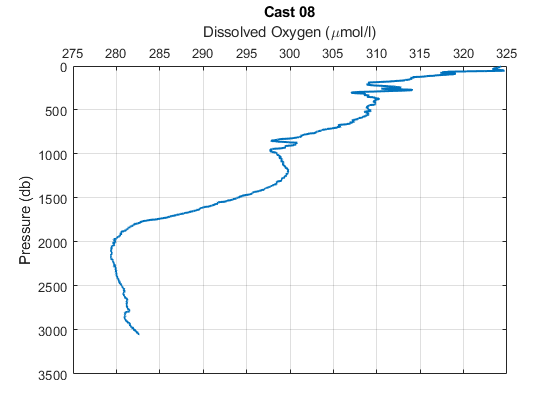


figure
plot(cast08.sbeox0mL_L*44.661,cast08.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 08')

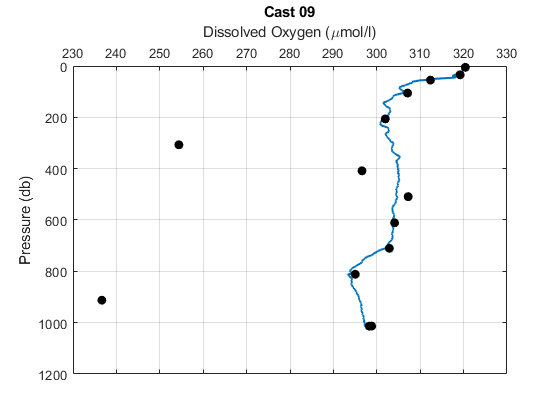


figure
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
hold on
plot(btlsum09.Winkler_mLL*44.661,btlsum09.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')

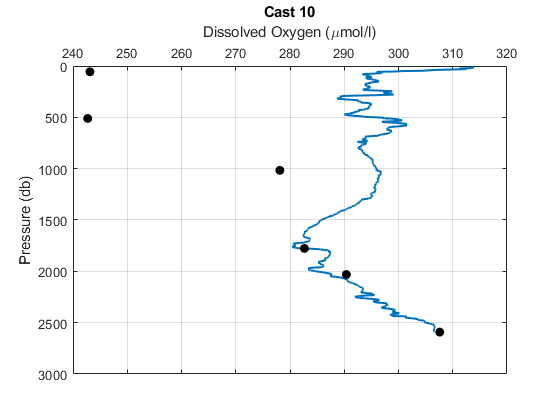


figure
plot(cast10.sbeox0mL_L*44.661,cast10.pm,'Linewidth',1.5)
hold on
plot(btlsum10.Winkler_mLL*44.661,btlsum10.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 10')

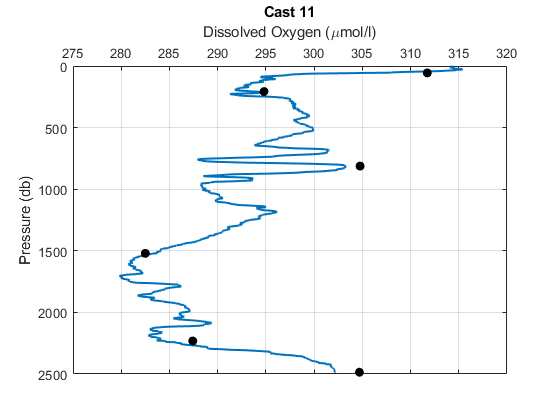


figure
plot(cast11.sbeox0mL_L*44.661,cast11.pm,'Linewidth',1.5)
hold on
plot(btlsum11.Winkler_mLL*44.661,btlsum11.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 11')

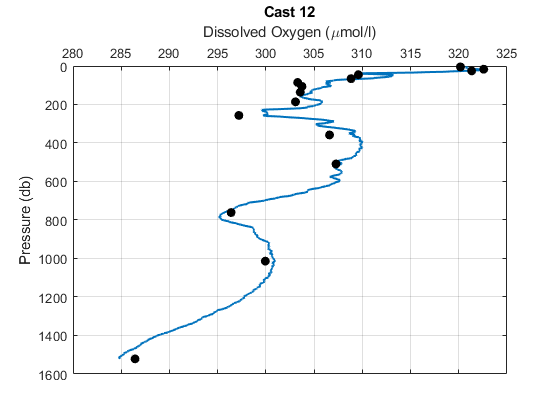


figure
plot(cast12.sbeox0mL_L*44.661/1.0395*1.05,cast12.pm,'Linewidth',1.5)
hold on
plot(btlsum12.Winkler_mLL*44.661,btlsum12.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 12')

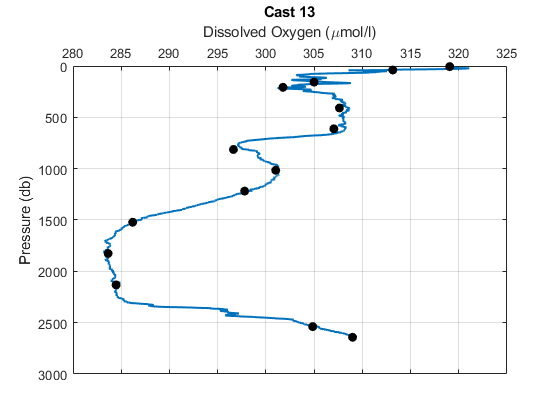


figure
plot(cast13.sbeox0mL_L*44.661/1.0395*1.05,cast13.pm,'Linewidth',1.5)
hold on
plot(btlsum13.Winkler_mLL*44.661,btlsum13.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 13')

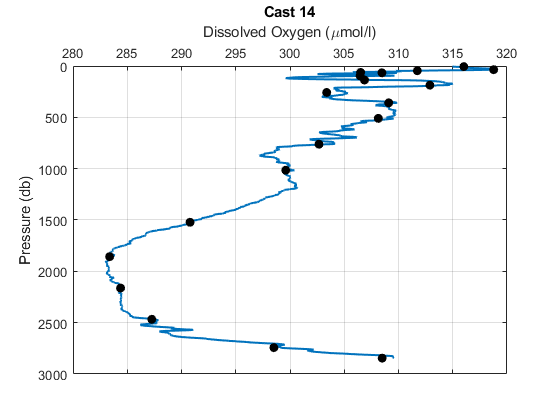


figure
plot(cast14.sbeox0mL_L*44.661/1.0395*1.05,cast14.pm,'Linewidth',1.5)
hold on
plot(btlsum14.Winkler_mLL*44.661,btlsum14.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 14')

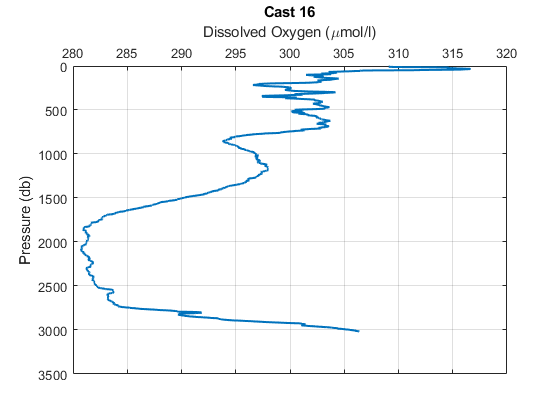


figure
plot(cast16.sbeox0mL_L*44.661,cast16.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 16')

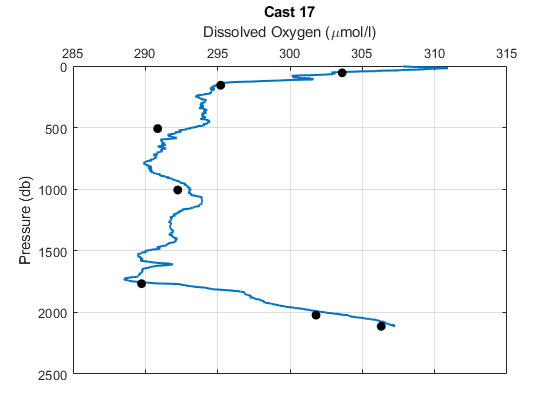


figure
plot(cast17.sbeox0mL_L*44.661/1.0395*1.05,cast17.pm,'Linewidth',1.5)
hold on
plot(btlsum17.Winkler_mLL*44.661,btlsum17.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 17')

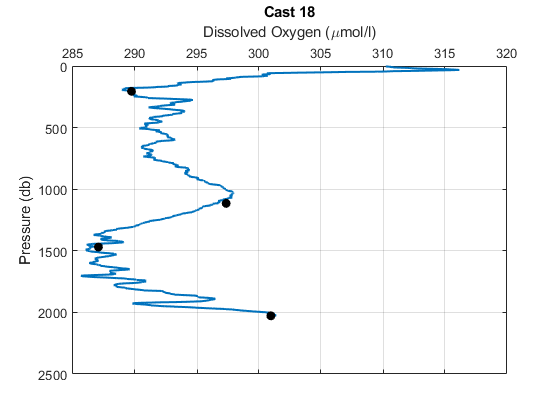


figure
plot(cast18.sbeox0mL_L*44.661/1.0395*1.05,cast18.pm,'Linewidth',1.5)
hold on
plot(btlsum18.Winkler_mLL*44.661,btlsum18.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 18')

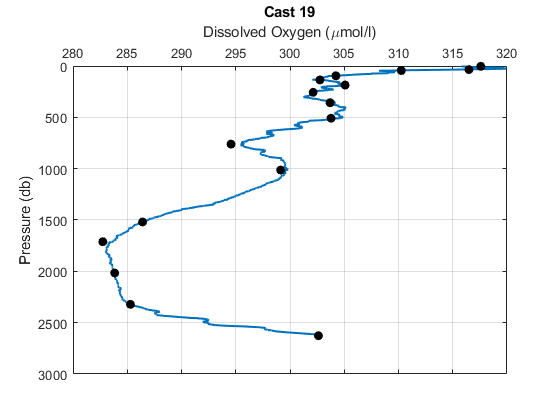


figure
plot(cast19.sbeox0mL_L*44.661/1.0395*1.05,cast19.pm,'Linewidth',1.5)
hold on
plot(btlsum19.Winkler_mLL*44.661,btlsum19.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 19')

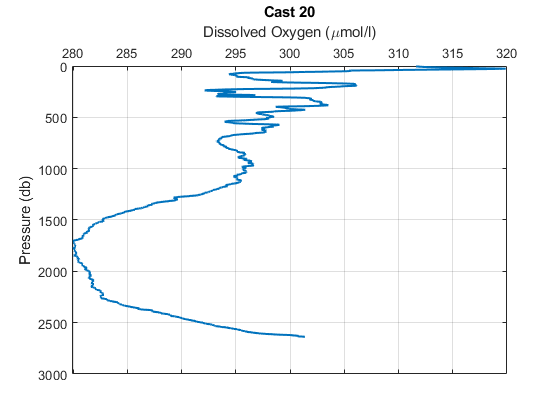


figure
plot(cast20.sbeox0mL_L*44.661,cast20.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 20')

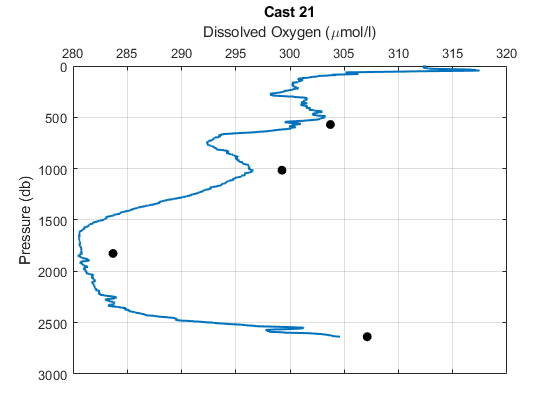


figure
plot(cast21.sbeox0mL_L*44.661,cast21.pm,'Linewidth',1.5)
hold on
plot(btlsum21.Winkler_mLL*44.661,btlsum21.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 21')

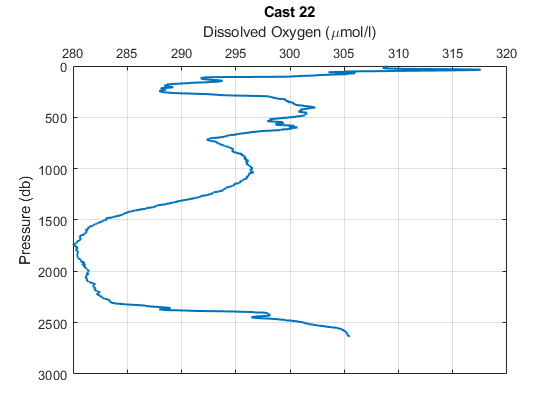


figure
plot(cast22.sbeox0mL_L*44.661,cast22.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 22')

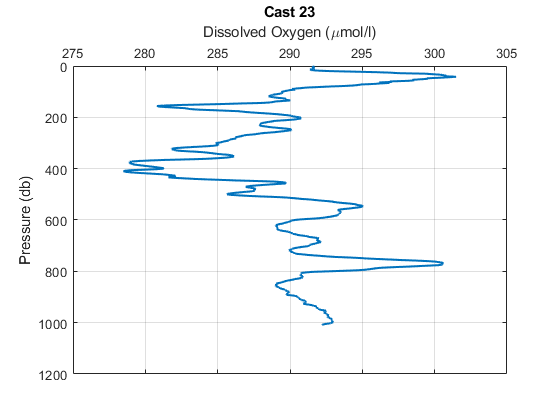


figure
plot(cast23.sbeox0mL_L*44.661,cast23.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 23')